%addpath("c:/git/UQ4PDE_Homeworks/Homework 1/Part 2/MATLAB functions/")
addpath("c:/git/UQ4PDE_Homeworks/Homework 1/Part 2/Covariance functions/")

`Task 2`

Modelling random fields $a(x,w)$

`Model 1: Piecewise constant coefficients`

We would like to sample the random field

                                
$$a(x,w) = 1+\sigma\sum_{n=1}^N Y_n(w)\mathbf{1}_{[\hat{x}_{n-1},\hat{x}_n]}(x)$$


with equidistant nodes $\hat{x}_n=\frac{n}{N}$ for $0\leq n\leq N$ and i.i.d.uniform RVs $Y_n\sim U([-\sqrt{3},\sqrt{3}])$.

%{
% Mesh to define random field
N = 40;

% Set a value for sigma
sigma = 0.5;

% Interval on which we evaluate the random field
l = 4;
I = N*2^l; % Mesh for numerical approximation of discr. PDE

x = linspace(0, 1, I);

Y = a_constant_coeff(x, N, sigma);

plot(x, Y);
title('Sample of model 1')
%}

`Model 2: Log normal`

No we would like to sample the random field defined by

                                
$$a(x,w) = \exp(\kappa(x,w))$$


where $\kappa(x,w)$ is a stationary Gaussian random field with mean zero and the Mátern covariance function

                
$$C(x,y) = \sigma^2\frac{1}{\Gamma(\nu)2^{\nu-1}}\left(\sqrt{2\nu}\frac{|x-y|}{\rho}\right)^\nu K_\nu\left(\sqrt{2\nu}\frac{|x-y|}{\rho}\right)$$


where $\Gamma$ is the Gamma function and $K_\nu$ is the modified Bessel function of the second kind. We will look at special cases

- `Case: `$\nu=0.5$, $C(x,y)=\sigma^2\exp\left(-\frac{|x-y|}{\rho}\right)$

- `Case: `$\nu=1.5$, $C(x,y)=\sigma^2\left(1+\frac{\sqrt{3}|x-y|}{\rho}\right)\exp\left(-\frac{\sqrt{3}|x-y|}{\rho}\right)$

- `Case: `$\nu=2.5$, $C(x,y)=\sigma^2\left(1+\frac{\sqrt{5}|x-y|}{\rho}+\frac{\sqrt{3}|x-y|}{\rho^2}\right)\exp\left(-\frac{\sqrt{5}|x-y|}{\rho}\right)$

- `Case: `$\nu\to\infty
$, $C(x,y)=\sigma^2\exp\left(-\frac{|x-y|^2}{2\rho^2}\right)$

Moreover we choose $\rho=0.1$ and $\sigma^2=2$.

- `Possible approximation: Cholesky/SV decomposition`

We will now sample these covarianc functions using a Grid on $[0,1]$. For that we need to construction covariance matrices given an input mesh $X$.

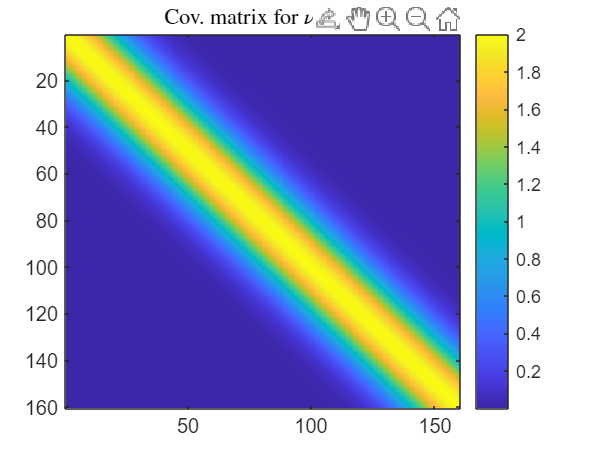


nu = 'infinity';
X = linspace(0, 1, I);
C = Matern_specialcases_only(X, nu);

% We plot the corresponding covariance matrix using a color plot
imagesc(C)
title('Cov. matrix for $\nu=\infty$', 'Interpreter', 'latex')

colorbar


Now we can do a Cholesky-Decomposition (for example, could also use singular value decomp.) to get the matrix $A$ such that $C=AA^T$.

%{
if (nu == 0.5 | nu == 1.5)
    A = chol(C,'lower');
end

if (nu == 2.5 | nu == 'infinity')
    [U,S,V] = svd(C);
    S_sqrt = sqrt(S);
    A = U*S_sqrt;
end
%}

And finally we can sample the random field $\kappa(x,w)$, namely $X_h$, on the grid by sampling a standart Gaussian $Z\sim\mathcal{N}(0,I)$ and get the sample of our random field (since we have mean zero) by $X_h = AZ$.

%Z = normrnd(0, 1, [I 1]);
%X_h = exp(mtimes(A, Z));

We can also plot this

%semilogy(X, X_h);
%title('Sample of model 2 (nu=0.5)')

I also implemented this procedure in a single function.

%Y = a_matern(X, nu);
%semilogy(X, Y)

             2. `Possible approximation: Karhunen-Loève expansion`

Now we want to sample the random field using a Karhunen-Loève expansion with $N$ terms

                            
$$\kappa(x,w)\approx\sum_{n=1}^N\sqrt{\lambda_n}Y_n(w)e_n(w)$$


where $\{Y_n\}$ is a set of i.i.d. standart Gaussians. To find the eigenfunctions and eigenvalues of our covariance function $C$, we solve the eigenproblem

       (1)                     $\int_0^1 C(x,y)e_n(y)dy = \lambda_ne_n(x)$

We do this by discretizing $C$ as a matrix by evaluating the function $C(x_{i+\frac{1}{2}},x_{j+\frac{1}{2}})$ over the grid $\{x_{i+\frac{1}{2}}\}_{i=0}^{I-1}\times\{x_{i+\frac{1}{2}}\}_{i=0}^{I-1}$ with $N\leq I$. Then use `MATLAB`'s function `eig().` The discretization corresponds to a piecewise FEM approximation to the eigenvalue problem (1). We will make sure that the computed eigenfunctions have norm 1 with respect to the continuous $L^2([0,1])$ norm.

To that extend, we will first introduce the named grid

%{
l = 3;
N = 20;
I = N*2^l
x = linspace(0, 1, I+1);
x_half = zeros([I+1 1]);
for k=1:I
    x_half(k) = (x(k+1) + x(k))/2; 
end
%}

Now we will compute the covariance matrix on this grid

%{
nu = 0.5;
Cov_a_1 = Matern_specialcases_only(x_half, 0.5);
Cov_a_2 = Matern_specialcases_only(x_half, 1.5);
Cov_a_3 = Matern_specialcases_only(x_half, 2.5);
Cov_a_4 = Matern_specialcases_only(x_half, 'infinity');
%}

Now we can calculate the corresponding eigenvalues, eigenvectors and transform them to get the singularvalues $\sqrt{\lambda_n}$ and norms we are interested in, namely, $\|e_n\|_{L^2}\stackrel{!}{=}1$ and $\|e_n\|_{\infty}$ to calculate the spectral contribution of each covariance matrix $C$, i.e. $\sqrt{\lambda_n}\|e_n\|_{\infty}$.

%{
[EVec_1, EVal_1] = eig(Cov_a_1);
[EVec_2, EVal_2] = eig(Cov_a_2);
[EVec_3, EVal_3] = eig(Cov_a_3);
[EVec_4, EVal_4] = eig(Cov_a_4);
SV_1 = zeros([I 1]);
SV_2 = zeros([I 1]);
SV_3 = zeros([I 1]);
SV_4 = zeros([I 1]);
LinfNorm_EVec_1 = zeros([I 1]);
LinfNorm_EVec_2 = zeros([I 1]);
LinfNorm_EVec_3 = zeros([I 1]);
LinfNorm_EVec_4 = zeros([I 1]);
L2Norm_EVec_1 = zeros([I 1]);
L2Norm_EVec_2 = zeros([I 1]);
L2Norm_EVec_3 = zeros([I 1]);
L2Norm_EVec_4 = zeros([I 1]);

spectralcontr_1 = zeros([I 1]);
spectralcontr_2 = zeros([I 1]);
spectralcontr_3 = zeros([I 1]);
spectralcontr_4 = zeros([I 1]);

for k=1:I
    SV_1(k) = sqrt(EVal_1(I+1-k, I+1-k));
    SV_2(k) = sqrt(EVal_2(I+1-k, I+1-k));
    SV_3(k) = sqrt(EVal_3(I+1-k, I+1-k));
    SV_4(k) = sqrt(EVal_4(I+1-k, I+1-k));
end
EVec_1 = flip(EVec_1, 2);
EVec_2 = flip(EVec_2, 2);
EVec_3 = flip(EVec_3, 2);
EVec_4 = flip(EVec_4, 2);

% Check whether we have continous L2-Norm for all eigenvectors
for k=1:I
    LinfNorm_EVec_1(k) = norm(EVec_1(:, k), "inf");
    LinfNorm_EVec_2(k) = norm(EVec_2(:, k), "inf");
    LinfNorm_EVec_3(k) = norm(EVec_3(:, k), "inf");
    LinfNorm_EVec_4(k) = norm(EVec_4(:, k), "inf");
    L2Norm_EVec_1(k) = norm(EVec_1(:, k), 2);
    L2Norm_EVec_2(k) = norm(EVec_2(:, k), 2);
    L2Norm_EVec_3(k) = norm(EVec_3(:, k), 2);
    L2Norm_EVec_4(k) = norm(EVec_4(:, k), 2);
    spectralcontr_1(k) = SV_1(k)*LinfNorm_EVec_1(k);
    spectralcontr_2(k) = SV_2(k)*LinfNorm_EVec_2(k);
    spectralcontr_3(k) = SV_3(k)*LinfNorm_EVec_3(k);
    spectralcontr_4(k) = SV_4(k)*LinfNorm_EVec_4(k);
end

loglog(1:I, spectralcontr_1, 1:I, spectralcontr_2, 1:I, spectralcontr_3, 1:I, spectralcontr_4)
title("Spectral contribution of Model 2 for diff. $\nu$'s", 'Interpreter', 'latex', fontsize=9)
legend('$\nu=0.5$', '$\nu=1.5$', '$\nu=2.5$', '$\nu\to\infty$', 'Interpreter', 'latex', fontsize=9, location='southwest')
%}

% Indeed we have constant ~1 as norms
%{
plot(1:I, L2Norm_EVec_1)
plot(1:I, L2Norm_EVec_2)
plot(1:I, L2Norm_EVec_3)
plot(1:I, L2Norm_EVec_4)
%}

Now we can use these Eigenvectors and singular values to get, together with i.i.d. standart Gaussians, the Karhunen-Loeven expansion of the random field $a(x,w)$

%{
Y_1 = normrnd(0, 1, [N 1]);
Y_2 = normrnd(0, 1, [N 1]);
Y_3 = normrnd(0, 1, [N 1]);
Y_4 = normrnd(0, 1, [N 1]);
inner1 = zeros([I+1 N]);
inner2 = zeros([I+1 N]);
inner3 = zeros([I+1 N]);
inner4 = zeros([I+1 N]);
for k=1:N
    inner1(:, k) = SV_1(k)*Y_1(k).*EVec_1(:, k);
    inner2(:, k) = SV_2(k)*Y_2(k).*EVec_2(:, k);
    inner3(:, k) = SV_3(k)*Y_3(k).*EVec_3(:, k);
    inner4(:, k) = SV_4(k)*Y_4(k).*EVec_4(:, k);
end
kappa_1 = sum(inner1, 2);
kappa_2 = sum(inner2, 2);
kappa_3 = sum(inner3, 2);
kappa_4 = sum(inner4, 2);

a_KL_1 = exp(kappa_1);
a_KL_2 = exp(kappa_2);
a_KL_3 = exp(kappa_3);
a_KL_4 = exp(kappa_4);


plot(x_half(1:end-1), kappa_1(1:end-1), x_half(1:end-1), kappa_2(1:end-1), x_half(1:end-1), kappa_3(1:end-1), x_half(1:end-1), kappa_4(1:end-1))
title("Sample paths of $\kappa(x,w)$ using KL Expansion for diff. $\nu$", "Interpreter", 'latex', fontsize=8)
legend('$\nu=0.5$', '$\nu=1.5$', '$\nu=2.5$', '$\nu=\infty$', 'Interpreter', 'latex', fontsize=7)

semilogy(x_half(1:end-1), a_KL_1(1:end-1), x_half(1:end-1), a_KL_2(1:end-1), x_half(1:end-1), a_KL_3(1:end-1), x_half(1:end-1), a_KL_4(1:end-1))
title("Sample paths of $a(x,w)=\exp(\kappa(x,w))$ using KL Expansion for diff. $\nu$", "Interpreter", 'latex', fontsize=7)
legend('$\nu=0.5$', '$\nu=1.5$', '$\nu=2.5$', '$\nu=\infty$', 'Interpreter', 'latex', fontsize=7)
%}

Now we are interested in implementing this procedure as a function which returns a sample path of $a(x,w)$ using KL expansion.

%sample = a_KL_expansion(x, 0.5, N);
%plot(x, sample)

        `3. Possible approximation: Fourier expansion`

Now we will use a Fourier expansion of a periodic extension of the covariance field, namely            

                                            $\text{Cov}_{\kappa}^{\#}(x-y) = \sum_{n=0}^{\infty} \kappa_n^2\cos\left(\frac{n\pi(x-y)}{L_p}\right)$.

Take $L_p=2$ for instance. As a result, the stationary random field $\kappa$ admits the exact representation in $[0,L_p]$

                        
$$\kappa(x,w) = \sum_{n=0}^{\infty}\kappa_n\left( y_n(w)\cos\left(\frac{n\pi x}{L_p}\right) + z_n(w)\sin\left(\frac{n\pi x}{L_p}\right)\right)$$


and $\mathbb{E}[y_n] = \mathbb{E}[z_n]=0$, $\text{Var}[y_n]=\text{Var}[z_n] = 1$ and $\{y_n,z_n\}$ are uncorrelated Gaussians.

%{
% Sample the statiornary covariance function w.r.t. the distance from the
% origin
N_linspace = 500;
N = 50;
Lp = 2;
nu = 0.5;
x = linspace(0, 1, N_linspace);
y = stationary_matern(x, nu);

plot(x, y)

% Calculate the Fourier coeffiecients
kappa_n = sqrt(fft(y)/N_linspace);

loglog(1:length(kappa_n), kappa_n)

% Sample the random field
Y = normrnd(0, 1, [N 1]);
Z = normrnd(0, 1, [N 1]);


innersum = zeros([N N_linspace]);

for i=1:N
    innersum(i, :) = real(kappa_n(i))*(Y(i)*cos((i*pi*x)/Lp) + Z(i)*sin((i*pi*x)/Lp));
end

k = exp(sum(innersum, 1));
sample = a_KL_expansion(x, 0.5, N);
plot(x, sample)

plot(x, k)
%}